clc;clear all;

# LQG for ATMD system

## ATMD system

$x = [x_1 \,\, x_2 \,\, x_3 \,\, x_4]^T$ where

$x_1 = x_f$, $x_2=\dot{x}_f$, $x_3 = x_T$ and $x_4 = \dot{x}_T$.

As outputs we have $y = [\ddot{x}_g \,\, x_T]^T$ from an accelerometer and an encoder

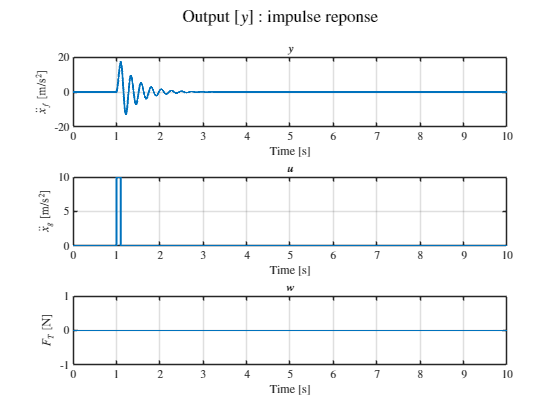

k_f = 500;
c_f = 3;
m_f = 0.68;
m_c = 0.39;
k_c = 0;
c_c = 0.5;
dt = 0.001;
t_f = 10;
Par = [k_f,c_f,m_f,m_c,c_c];
Ts = 1e-3;
[SYS,dSYS] = generateSateSpace(Par,Ts);

t = 0:dt:t_f;
ddx_g = 10*(t>1)-10*(t>1.1);
% sine: 1*sin(10*t);
% unit = 10*(t>1)
F_T = zeros(1,length(t));

u = [ddx_g;
    F_T];

[Y,~,X,~] = lsim(SYS,u,t);

%%%%%%%%%%%%%%

figure;
subplot(3,1,1)
plot(t,Y(:,1),'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\ddot{x}_f$ [m/s$^2$]','Interpreter','latex')
title('$y$','Interpreter','latex')
grid on

subplot(3,1,2)
plot(t,ddx_g,'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\ddot{x}_g$ [m/s$^2$]','Interpreter','latex')
title('$u$','Interpreter','latex')
grid on

subplot(3,1,3)
plot(t,F_T,'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$F_T$ [N]','Interpreter','latex')
title('$w$','Interpreter','latex')
grid on
sgtitle({'Output [$y$] : impulse reponse'},'Interpreter','latex')

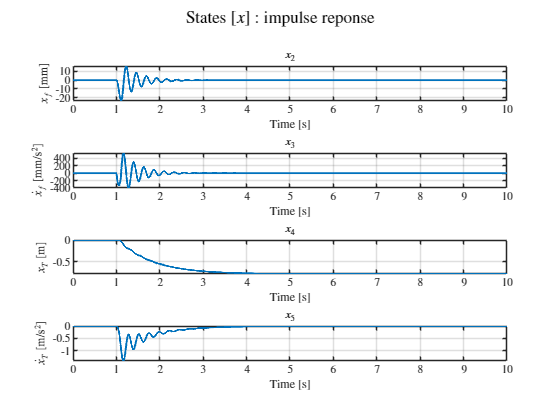

%%%%%%%%%%%%%%
figure;
subplot(4,1,1)
plot(t,X(:,1)*1000,'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$x_f$ [mm]','Interpreter','latex')
title('$x_2$','Interpreter','latex')
grid on

subplot(4,1,2)
plot(t,X(:,2)*1000,'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\dot{x}_f$ [mm/s$^2$]','Interpreter','latex')
title('$x_3$','Interpreter','latex')
grid on

subplot(4,1,3)
plot(t,X(:,3),'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$x_T$ [m]','Interpreter','latex')
title('$x_4$','Interpreter','latex')
grid on

subplot(4,1,4)
plot(t,X(:,4),'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\dot{x}_T$ [m/s$^2$]','Interpreter','latex')
title('$x_5$','Interpreter','latex')
grid on
sgtitle({'States [$x$] : impulse reponse'},'Interpreter','latex')

## Earthquake signal

We use the  Kanai-Tajimi method to generate artificial accelerometer data to use it for $\ddot{x}_g$

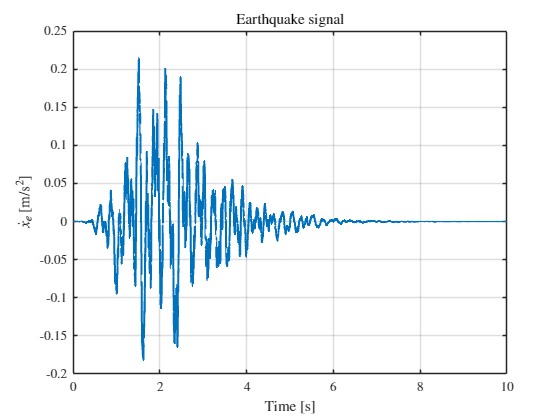

f_e = linspace(0,1/dt,10048); % frequency vector
zeta = 0.3; % bandwidth of the earthquake excitation.
sigma = 0.3; % standard deviation of the excitation.
fn =5; % dominant frequency of the earthquake excitation (Hz).
T90 = 0.3; % value of the envelop function at 90 percent of the duration.
eps = 0.4; % normalized duration time when ground motion achieves peak.
tn = 5; % duration of ground motion (seconds).

% function call
[ddx_e,~] = seismSim(sigma,fn,zeta,f_e,T90,eps,tn); 
% y: acceleration record
% t: time

figure
plot(t,ddx_e(1:length(t)),'LineWidth',1.5);
xlabel('Time [s]','Interpreter','latex')
ylabel('$\dot{x}_e$ [m/s$^2$]','Interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
grid on
title('Earthquake signal','Interpreter','latex')

## Reaction to earthquake signal

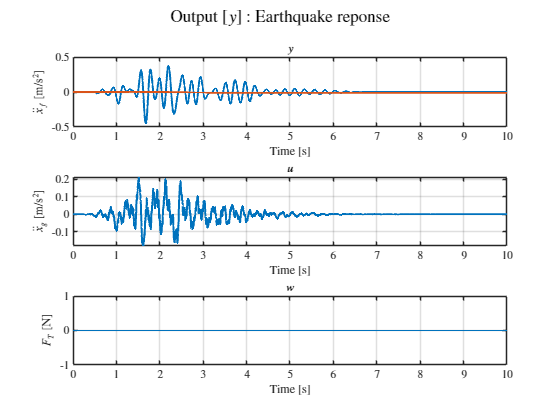

u = [ddx_e(1:length(t));
    F_T];

[Y_e,~,X_e,~] = lsim(SYS,u,t);

%%%%%%%%%%%%%%

figure;
subplot(3,1,1)
plot(t,Y_e,'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\ddot{x}_f$ [m/s$^2$]','Interpreter','latex')
title('$y$','Interpreter','latex')
grid on

subplot(3,1,2)
plot(t,u(1,:),'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\ddot{x}_g$ [m/s$^2$]','Interpreter','latex')
title('$u$','Interpreter','latex')
grid on

subplot(3,1,3)
plot(t,u(2,:),'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$F_T$ [N]','Interpreter','latex')
title('$w$','Interpreter','latex')
grid on

sgtitle({'Output [$y$] : Earthquake reponse'},'Interpreter','latex')

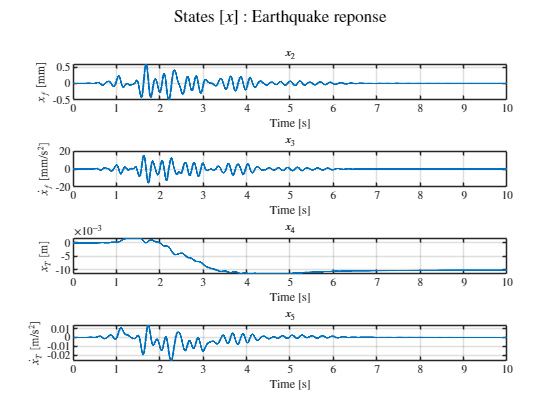


%%%%%%%%%%%%%%
figure;
subplot(4,1,1)
plot(t,X_e(:,1)*1000,'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$x_f$ [mm]','Interpreter','latex')
title('$x_2$','Interpreter','latex')
grid on

subplot(4,1,2)
plot(t,X_e(:,2)*1000,'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\dot{x}_f$ [mm/s$^2$]','Interpreter','latex')
title('$x_3$','Interpreter','latex')
grid on

subplot(4,1,3)
plot(t,X_e(:,3),'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$x_T$ [m]','Interpreter','latex')
title('$x_4$','Interpreter','latex')
grid on

subplot(4,1,4)
plot(t,X_e(:,4),'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\dot{x}_T$ [m/s$^2$]','Interpreter','latex')
title('$x_5$','Interpreter','latex')
grid on
sgtitle({'States [$x$] : Earthquake reponse'},'Interpreter','latex')

## LQG

% LQR
% Q = diag([5e5 4e3 .001 .001]); works for v = 0;
Q = diag([2e5 4e3 .001 .001]); % 
% Ts = 1e-3;

R = 1;
K = lqrd(SYS.A,SYS.B(:,2),Q,R,Ts)

K =  -653.6434    3.1739    0.0316    0.8429



Q_k = 0.1; % Process noise
R_k = 0.1*eye(2); % measurement noise

[~,L,~] = kalmd(SYS,Q_k,R_k,Ts)

L =    -0.0000    0.0000
    0.0000   -0.0000
   -0.0000    0.0013
    0.0000    0.0009


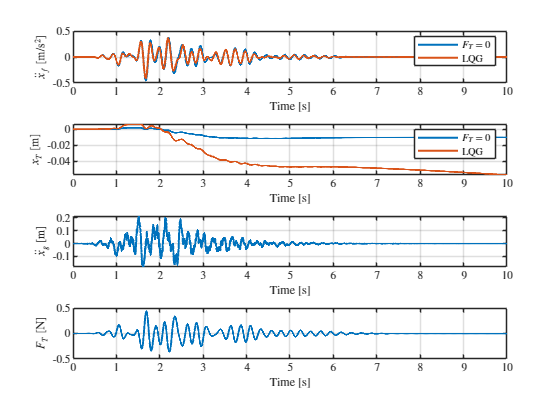


% dSYS = c2d(SYS,Ts,'zoh');

A_k = (SYS.A+SYS.B(:,2)*K+L*SYS.C);
% A_k = (A-B(:,2)*K-L*C);

B_k = [SYS.B(:,1) -L];
% B_k = [B(:,1) L];

C_k = eye(size(SYS.A));

D_k = 0;

SYS_cl = ss(A_k,B_k,C_k,D_k);
dSYS_cl = c2d(SYS_cl,Ts,'zoh');

x_0 = [0 0 0 0]';
x_k_0 = [0 0 0 0]';

y_lqg = zeros(1,length(t));

x_k = zeros(length(SYS.A),length(t));
x_k(:,1) = x_k_0;

x = zeros(length(SYS.A),length(t));
x(:,1) = x_0;

y = zeros(size(SYS.C,1),length(t));

ddx_g_lqr = ddx_e(1:length(t));

for i = 1:length(t)
    x(:,i+1) = dSYS.A*x(:,i)+dSYS.B*[ddx_g_lqr(i);-K*x_k(:,i)];
    y(:,i) = dSYS.C*x(:,i); 
    x_k(:,i+1) = dSYS_cl.A*x_k(:,i) + dSYS_cl.B*[ddx_g_lqr(i);y(:,i)];
end

figure;

subplot(4,1,1)
plot(t,Y_e(:,1),'LineWidth',1.5)
hold on
plot(t,y(1,:),'LineWidth',1.5,'LineStyle','-')
legend({'$F_T = 0$','LQG'},'Interpreter','Latex')
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\ddot{x}_f$ [m/s$^2$]','Interpreter','latex')
grid on

subplot(4,1,2)
plot(t,Y_e(:,2),'LineWidth',1.5)
hold on
plot(t,y(2,:),'LineWidth',1.5,'LineStyle','-')
legend({'$F_T = 0$','LQG'},'Interpreter','Latex')
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$x_T$ [m]','Interpreter','latex')
grid on

subplot(4,1,3)
plot(t,ddx_g_lqr,'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\ddot{x}_g$ [m]','Interpreter','latex')
grid on

subplot(4,1,4)
plot(t,-K*x_k(:,1:end-1),'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$F_T$ [N]','Interpreter','latex')
grid on